# PIDSolver

Bodeplot for G(s):

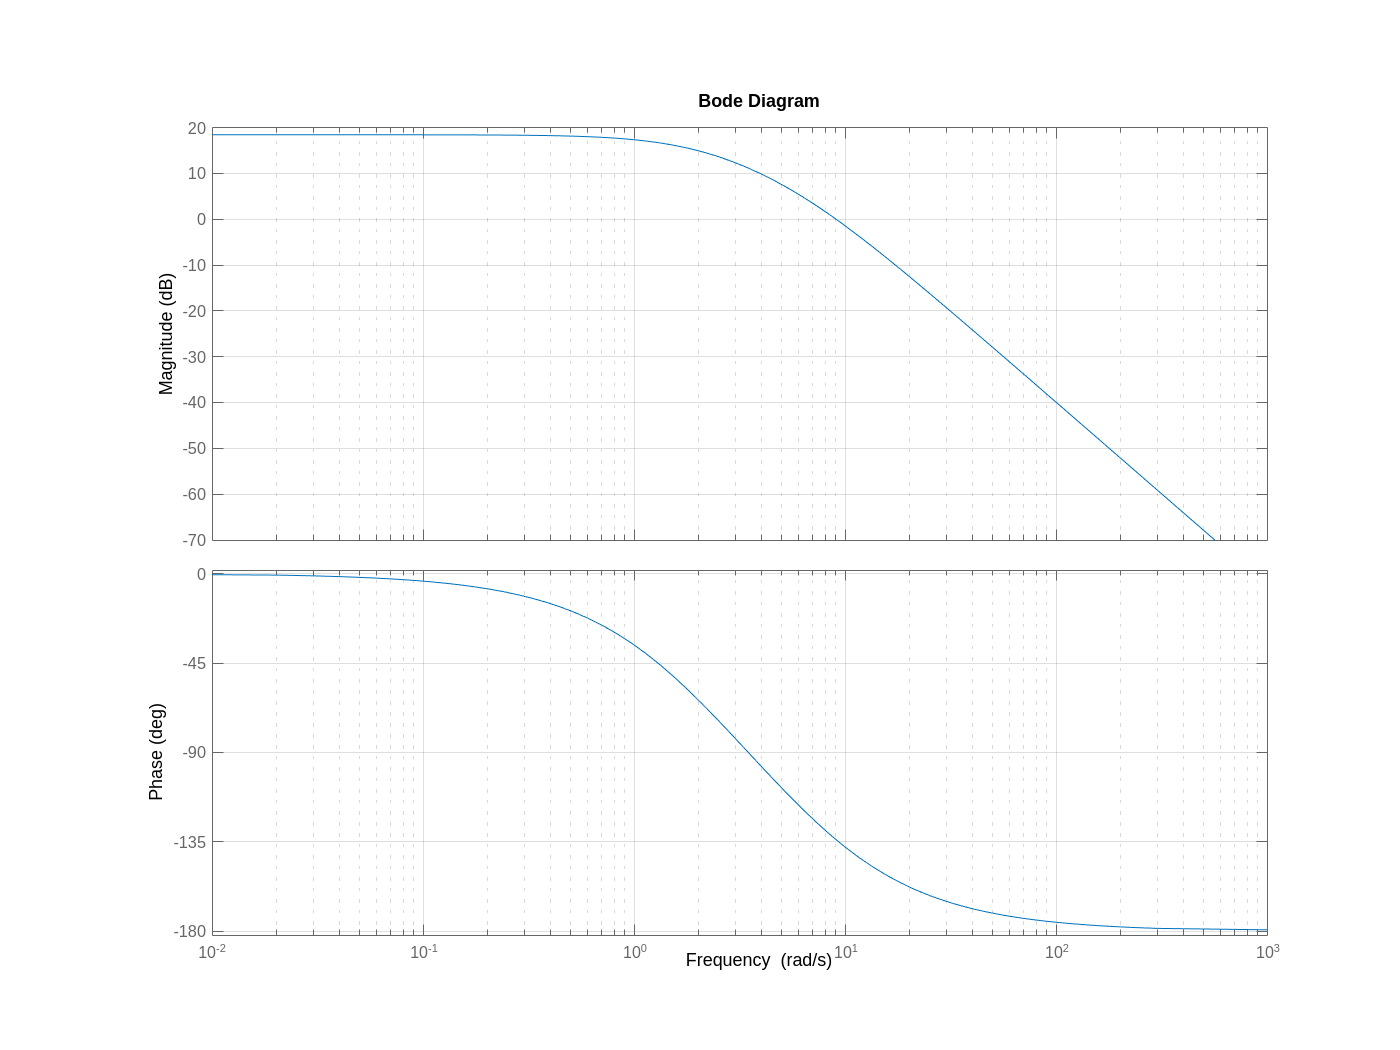

-----------------------

zeta = 0.5169

OS = 15.0000

phase_margin = 53.1718

w_bw = 96.9143

-----------------------

Kp = 39.4740


Bodeplot for G(s) * Kp:

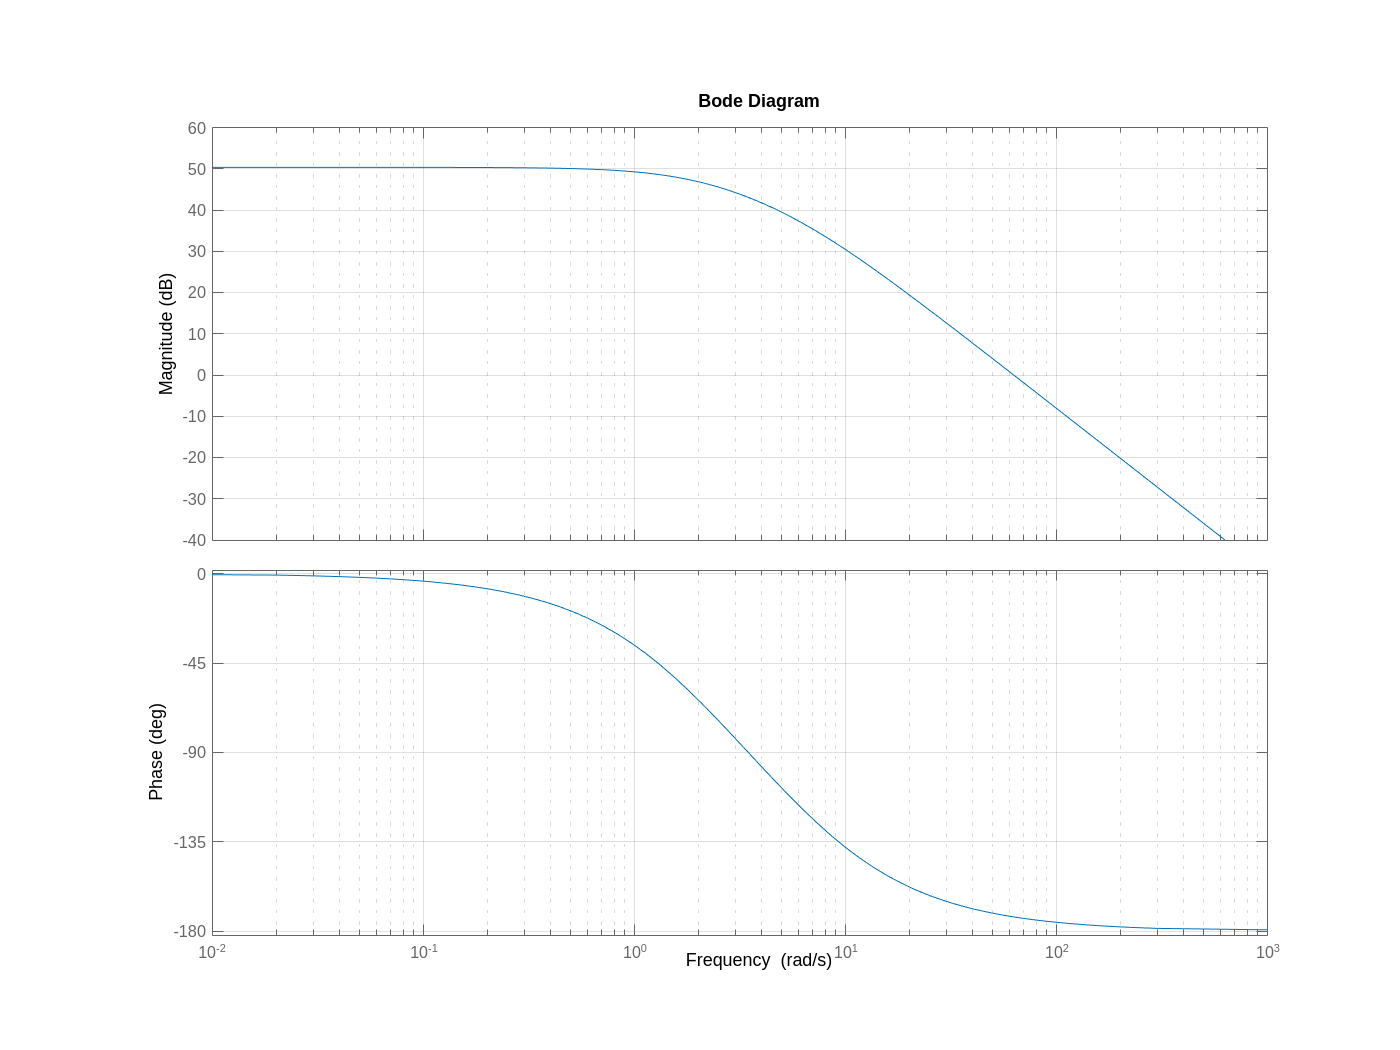

-----------------------

Td = 0.0206

Tf = 0.0034

-----------------------
Bodeplot for G_PD(s):

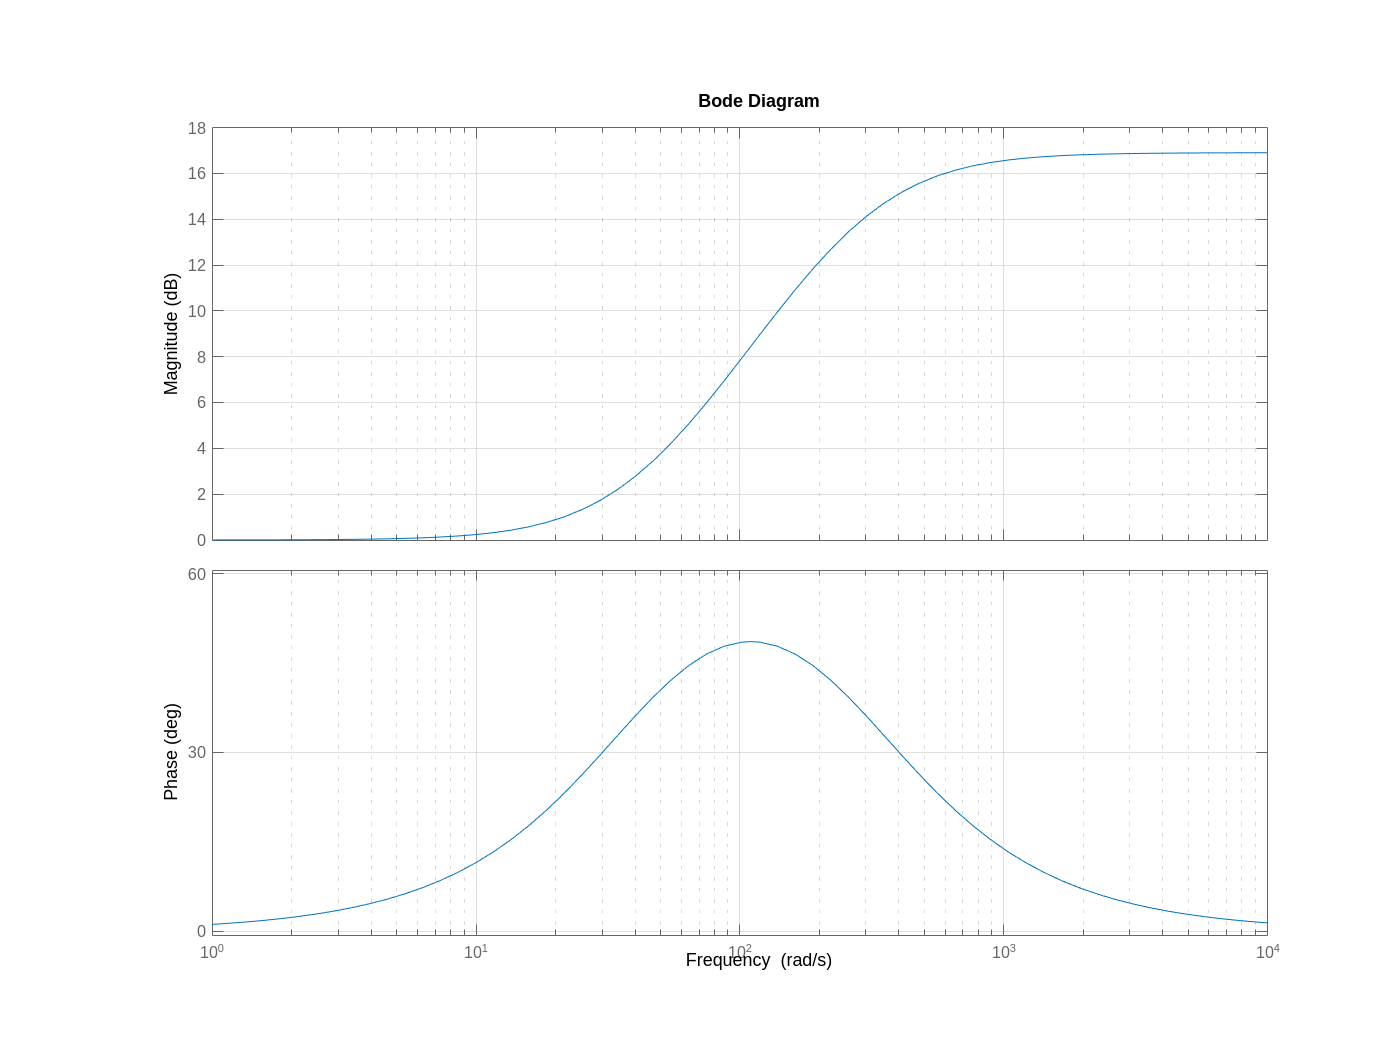

-----------------------

Ti = 0.2064

-----------------------
Bodeplot for G_PI(s):

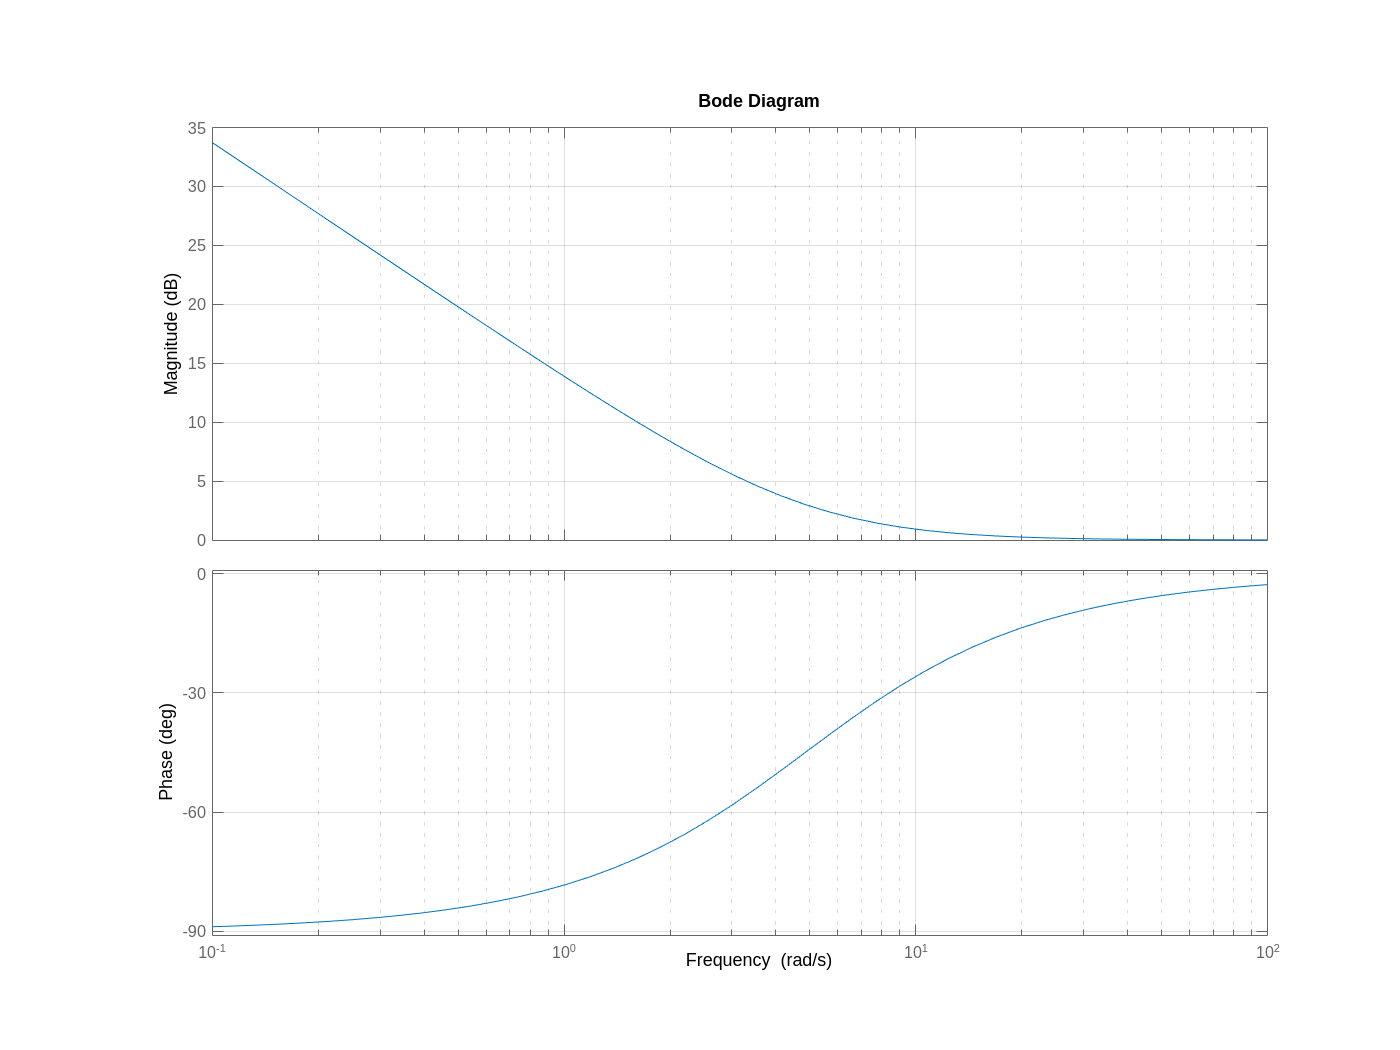

-----------------------
Bodeplot after applying G_PD and G_PI to G(s):

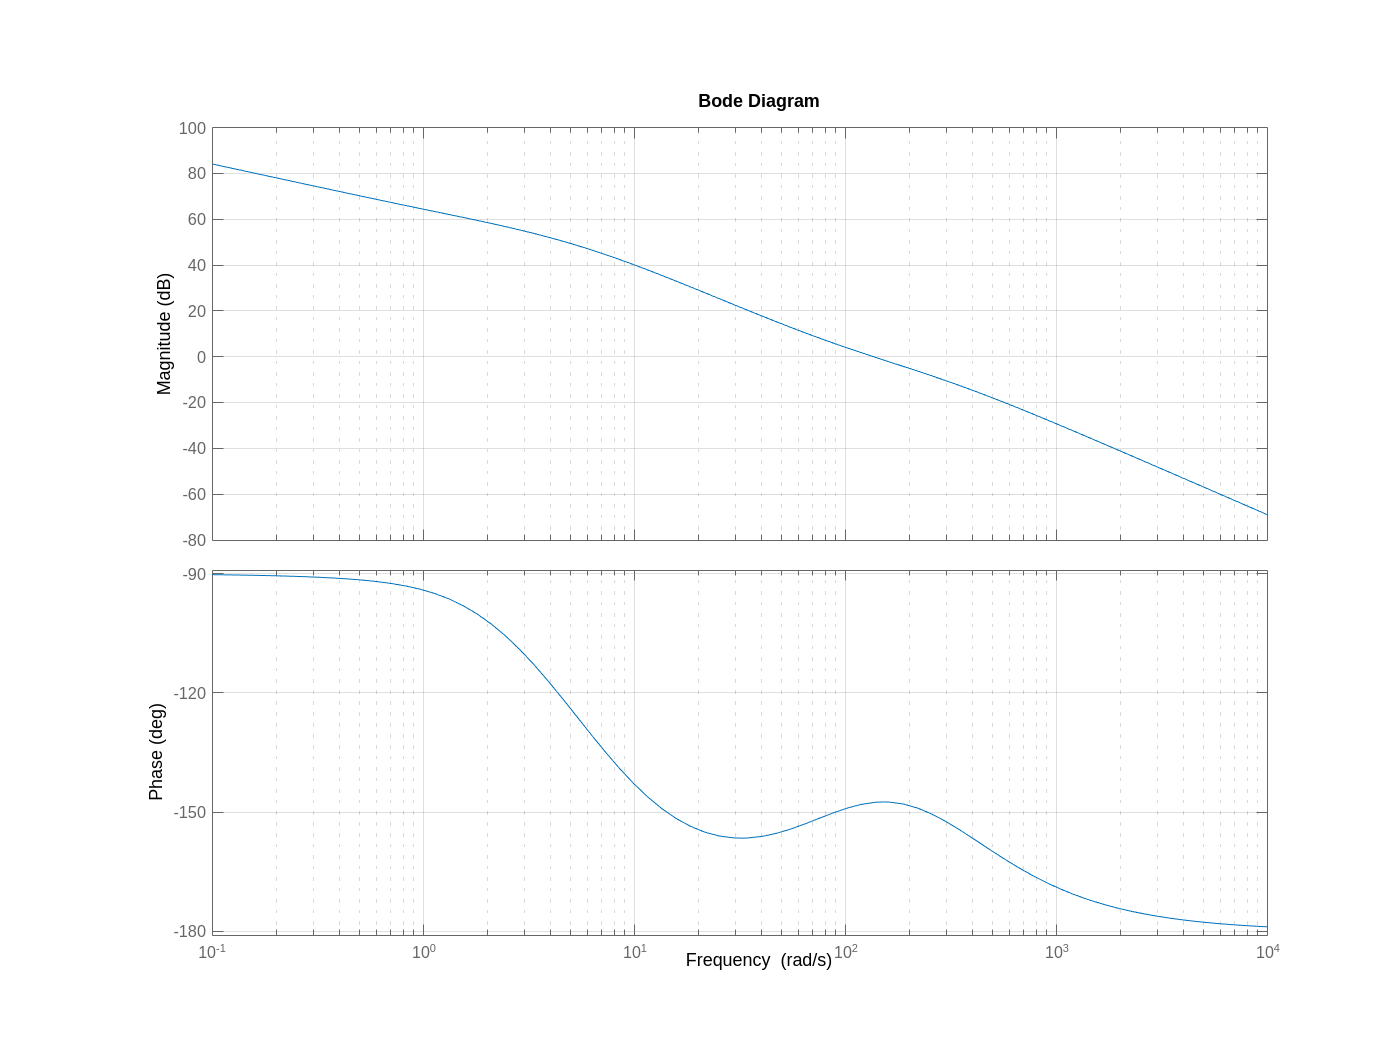

Step response of closed loop G(s):

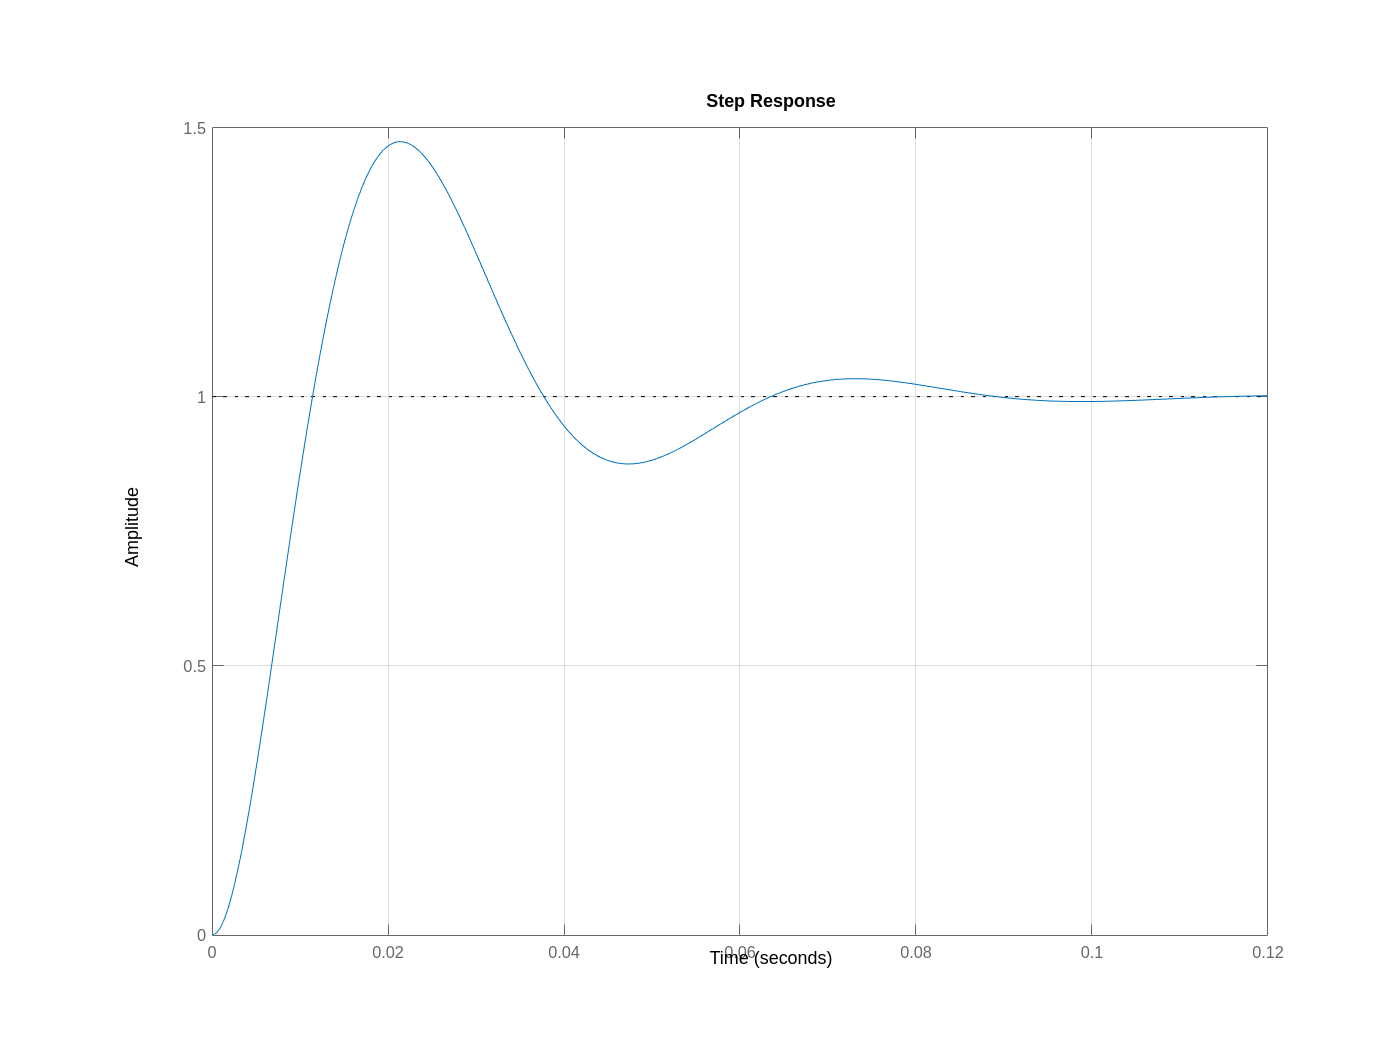

result = struct with fields:
         RiseTime: 0.0078
    TransientTime: 0.0811
     SettlingTime: 0.0811
      SettlingMin: 0.8750
      SettlingMax: 1.4737
        Overshoot: 47.3724
       Undershoot: 0
             Peak: 1.4737
         PeakTime: 0.0213


% testbench:
s = tf('s');
G = (100 * (s+1)) / ((s+1) * (s+2) * (s+6));
Ts = 0.1;
OS = 15;


PIDSolver(G, Ts, OS)

% function code:
% G = Transfer function
% Ts = Settlingtime
% OS = Max % Overshoot

function PIDSolver(G, Ts, OS)
    % Step: Init
    s = tf('s');
    fprintf("Bodeplot for G(s):")
    figure; bode(G); grid on;

    fprintf("-----------------------")
    
    % Step: Find: zeta, %OS, phasemargin and phasemargin-frequency
    %% Calculate zeta from %OS
    zeta = (-log(OS/100)) / (((pi^2 + log(OS/100)^2))^(1/2))

    %% Calculate overshoot
    Cmax = (1 + exp(-((zeta*pi)/sqrt(1-zeta^2))));
    OS = (Cmax-1)*100

    %% Calculate phasemargin
    phase_margin = atan((2*zeta) / (-2*zeta^2 + (1+(4*zeta^4))^(1/2))^(1/2));
    phase_margin = rad2deg(phase_margin)
    
    %% Calculate phasemargin-frequency
    w_bw = (4/(Ts*zeta)) * (sqrt((1-(2*zeta^2))+sqrt((4*zeta^4) - (4*zeta^2) + 2)))
    
    fprintf("-----------------------")

    % Step: Make Kp
    [mag,phase,wout] = bode(G,w_bw);
    mag = abs(mag2db(mag)); 

    Kp = (mag)
    G = G * Kp;

    fprintf("\nBodeplot for G(s) * Kp:")
    figure; bode(G); grid on;

    fprintf("-----------------------")

    % Step: Make G_PD part
    Td = 1/(w_bw/2)
    Tf = 1/(w_bw*3)
    G_PD = (1 + (s * Td) / (s * Tf + 1));
    
    fprintf("-----------------------")

    fprintf("\nBodeplot for G_PD(s):")
    figure; bode(G_PD); grid on;

    fprintf("-----------------------")

    % Step: Make G_PI part
    Ti = 20/w_bw
    G_PI = (((s * Ti) + 1) / (s * Ti));

    fprintf("-----------------------")

    fprintf("\nBodeplot for G_PI(s):")
    figure; bode(G_PI); grid on;

    fprintf("-----------------------")

    % Step: Make openloop plot of system after all filters
    G = G + (G*G_PD) + (G*G_PI);

    fprintf("\nBodeplot after applying G_PD and G_PI to G(s):")
    figure; bode(G); grid on;
    
    % Step: Final, Make stepresponse
    result = feedback(G,1);
    
    fprintf("Step response of closed loop G(s):")
    figure; step(result); grid on;
    result = stepinfo(result)
end

## Sources:

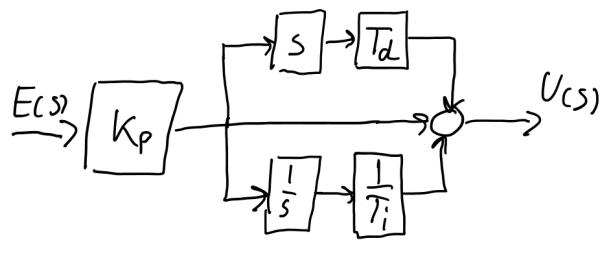

**Source**: E4IRT_L8_vE2101.pdf, page 24.

Note**: **The PID controller is implemented as in the above image. Kp in G_PD(s) and G_PI(s) will be removed respectively (as E(s) already is multiplied by Kp). 

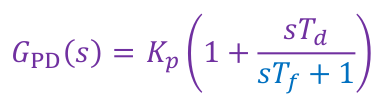

**Source**: E4IRT_L8_vE2101.pdf, page 11.

**Source**: E4IRT_L8_vE2101.pdf, page 18.

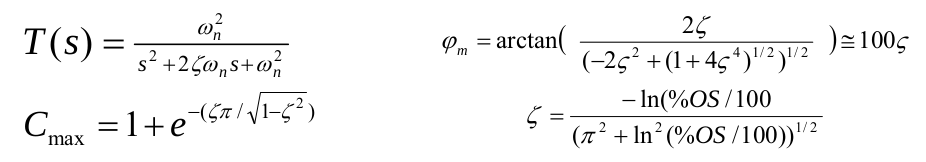

**Source**: Analysis and Design procedure.pdf, page 1.